# Plotter

Déclenchement de la commande évennementielle si les robots sont à +/-5cm. de la cible, ou que la direction de déplacement est décalé de +/- 10° par rapport au point cible.

## Comparaison des méthodes

clear all
close all
folder_event = 'event';
folder_classic = 'classic';
base_path = '~/mecanum/csv/';
ev = [0.85 0.1 0.1];  % Rouge classique
cl = [0.1 0.7 0.1];
folders = {'classic', 'event'};

### Trajectoires

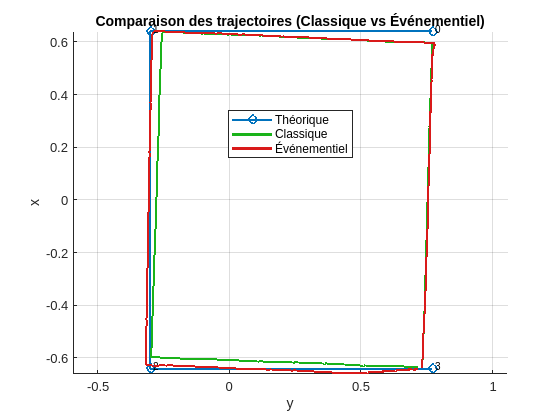

% === Lecture des trajectoires depuis les fichiers CSV ===
read_trajectory = @(folder) readtable(fullfile(base_path, folder, 'distributed_barycenter_logger.csv'));

data_classic = read_trajectory(folder_classic);
data_event = read_trajectory(folder_event);

% === Nouvelle lecture de la trajectoire théorique depuis un fichier CSV ===
filename_theory = fullfile(base_path, folder_classic, 'distributed_goal_point_logger.csv');
data_theory = readtable(filename_theory);

X_th = data_theory.x;
Y_th = data_theory.y;

% === Extraction des trajectoires réelles ===
x_classic = data_classic.x;
y_classic = data_classic.y;
x_event = data_event.x;
y_event = data_event.y;

% === Tracé des trajectoires ===
figure;
hold on; grid on; axis equal;

% Trajectoire théorique
plot(-Y_th, X_th, '-o', 'LineWidth', 1.5, 'MarkerSize', 6, 'DisplayName', 'Théorique');
for i = 1:length(X_th)
    text(-Y_th(i)+0.01, X_th(i)+0.01, num2str(i-1), 'FontSize', 8);
end

% Trajectoire réelle (classique)
plot(-y_classic, x_classic, '-', 'Color', cl, 'LineWidth', 2, 'DisplayName', 'Classique');

% Trajectoire réelle (événementiel)
plot(-y_event, x_event, '-', 'Color', ev, 'LineWidth', 2, 'DisplayName', 'Événementiel');

xlabel('y');
ylabel('x');
title('Comparaison des trajectoires (Classique vs Événementiel)');
legend('Location', 'best');

Note : Dans le programme, on considère un point comme étant atteint si le barycentre de l'essaim est à 5cm de la cible, d'où les légers écarts avec les points-cibles.

Les deux méthodes offrent des résultats similaires.

Note : le graph suivant ne marche pas pour les premieres versions de csv

     1



folder = 'classic'

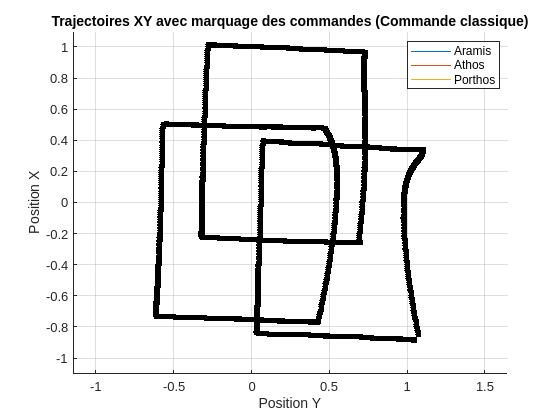

     2



folder = 'event'

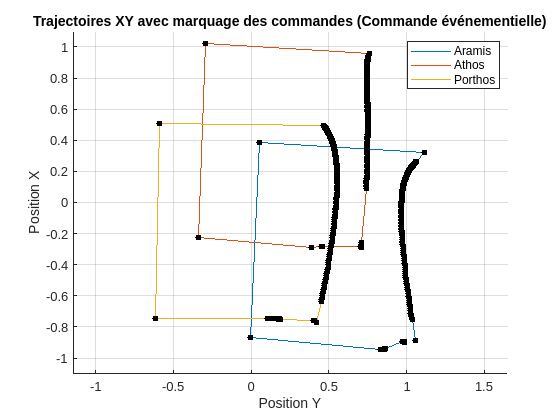


titles = {'Trajectoires XY avec marquage des commandes (Commande classique)', ...
          'Trajectoires XY avec marquage des commandes (Commande événementielle)'};

for k = 1:length(folders)
    disp(k)
    folder = folders{k}
    files = dir(fullfile(base_path, folder, '*_cmd_vel_rate.csv'));
    
    figure;
    hold on;
    axis equal;
    grid on;
    ylim([-1.1, 1.1]);  % Limites de l'axe Y

    
    colors = lines(length(files));
    legend_entries = {};
    plot_handles = gobjects(length(files),1);  % Pré-allocation des handles

    for i = 1:length(files)
        filename = fullfile(base_path, folder, files(i).name);
        data = readtable(filename, 'ReadVariableNames', false, 'Delimiter', ',');
        
        % Extraire les colonnes
        timestamps = datetime(data{:,1}, 'InputFormat', 'yyyy-MM-dd''T''HH:mm:ss.SSSSSS');
        x = data{:,2};
        y = data{:,3};
        
        % Tracer la trajectoire (handle enregistré pour la légende)
        plot_handles(i) = plot(-y, x, '-', 'Color', colors(i,:), 'LineWidth', 0.8);
        
        % Marquer les moments de commande sans ajouter à la légende
        scatter(-y, x, 20, 'k', 'filled', 'HandleVisibility', 'off');
        
        % Nom du robot
        robot_name = extractBefore(files(i).name, '_cmd_vel_rate.csv');
        legend_entries{end+1} = robot_name;
    end

    xlabel('Position Y');
    ylabel('Position X');
    title(titles{k});
    legend(plot_handles, legend_entries, 'Location', 'best');
end

### Temps

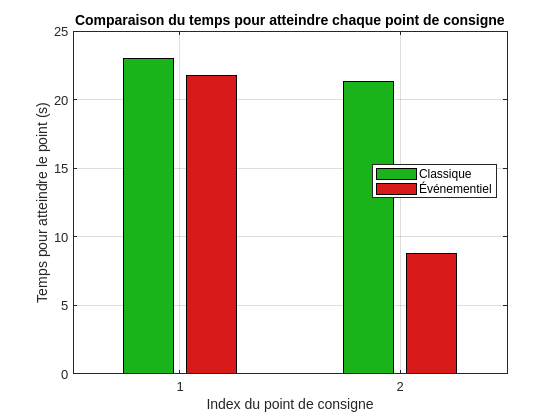

% === CLASSIC ===
folder = 'classic';
fichier_distance = fullfile(base_path, folder, 'distributed_distance_logger.csv');
fichier_trajectoire = fullfile(base_path, folder, 'distributed_goal_point_logger.csv');

% Lecture des données
data_classic = readtable(fichier_distance);
traj_classic = readtable(fichier_trajectoire);
time_abs_classic = datetime(data_classic{:,1}, 'InputFormat', 'yyyy-MM-dd''T''HH:mm:ss.SSSSSS');
time_classic = seconds(time_abs_classic - time_abs_classic(1));
time_goal_classic = seconds(datetime(traj_classic{:,1}, 'InputFormat', 'yyyy-MM-dd''T''HH:mm:ss.SSSSSS') - time_abs_classic(1));

% === EVENT ===
folder = 'event';
fichier_distance = fullfile(base_path, folder, 'distributed_distance_logger.csv');
fichier_trajectoire = fullfile(base_path, folder, 'distributed_goal_point_logger.csv');

data_event = readtable(fichier_distance);
traj_event = readtable(fichier_trajectoire);
time_abs_event = datetime(data_event{:,1}, 'InputFormat', 'yyyy-MM-dd''T''HH:mm:ss.SSSSSS');
time_event = seconds(time_abs_event - time_abs_event(1));
time_goal_event = seconds(datetime(traj_event{:,1}, 'InputFormat', 'yyyy-MM-dd''T''HH:mm:ss.SSSSSS') - time_abs_event(1));


% === Calcul des temps entre les points de consigne ===
delays_classic = diff(time_goal_classic);
delays_event = diff(time_goal_event);

% Limiter à la taille commune
n = min(length(delays_classic), length(delays_event));
delays_classic = delays_classic(1:n);
delays_event = delays_event(1:n);

% === Tracé en barplot avec couleurs personnalisées ===
figure;
b = bar([delays_classic, delays_event], 'grouped');
b(1).FaceColor = cl;  % Rouge pour Classique
b(2).FaceColor = ev;   % Vert pour Événementiel

xlabel('Index du point de consigne');
ylabel('Temps pour atteindre le point (s)');
legend('Classique', 'Événementiel', 'Location', 'best');
title('Comparaison du temps pour atteindre chaque point de consigne');
grid on;

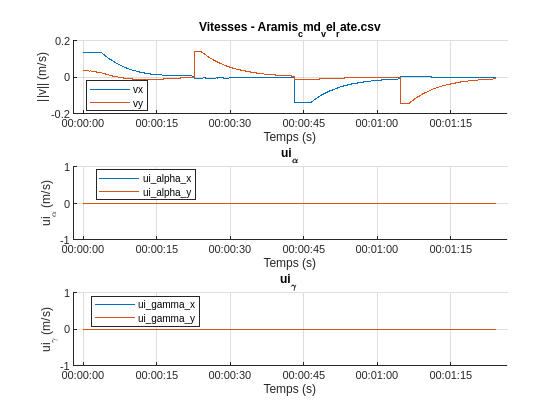

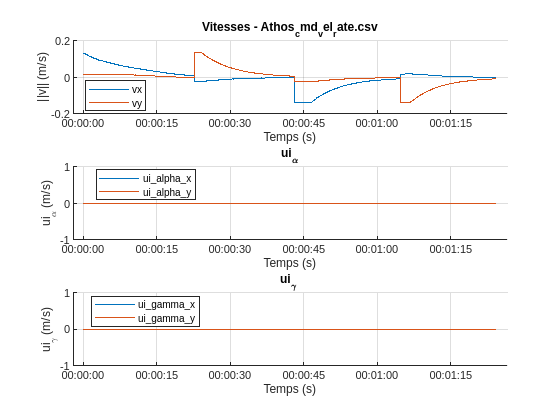

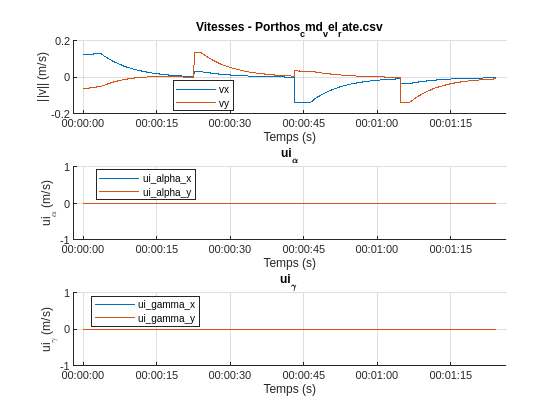


for k = 1:length(1)
    
    folder = folders{k};
    files = dir(fullfile(base_path, folder, '*_cmd_vel_rate.csv'));
    
    for f = 1:length(files)
        
        filepath = fullfile(files(f).folder, files(f).name);
        data = readtable(filepath);

        % Extraire les colonnes utiles
        t = data.timestamp - data.timestamp(1);  % temps en commençant à 0
        vx = data.linear_x;
        vy = data.linear_y;

        ui_gamma_x = data.ui_gamma_x;
        ui_gamma_y = data.ui_gamma_y;

        ui_alpha_x = data.ui_alpha_x;
        ui_alpha_y = data.ui_alpha_y;

        figure;
        
        % Subplot 1 : vx et vy
        subplot(3,1,1);
        hold on;
        plot(t, vx, 'DisplayName', 'vx');
        plot(t, vy, 'DisplayName', 'vy');
        xlabel('Temps (s)');
        ylabel('||v|| (m/s)');
        title(['Vitesses - ' files(f).name]);
        legend('Location', 'best');
        grid on;
        
        % Subplot 2 : ui_alpha_x et ui_alpha_y
        subplot(3,1,2);
        hold on;
        plot(t, ui_alpha_x, 'DisplayName', 'ui\_alpha\_x');
        plot(t, ui_alpha_y, 'DisplayName', 'ui\_alpha\_y');
        xlabel('Temps (s)');
        ylabel('ui_{\alpha} (m/s)');
        title(['ui_{\alpha}']);
        legend('Location', 'best');
        grid on;
        
        % Subplot 3 : ui_gamma_x et ui_gamma_y
        subplot(3,1,3);
        hold on;
        plot(t, ui_gamma_x, 'DisplayName', 'ui\_gamma\_x');
        plot(t, ui_gamma_y, 'DisplayName', 'ui\_gamma\_y');
        xlabel('Temps (s)');
        ylabel('ui_{\gamma} (m/s)');
        title(['ui_{\gamma} ' ]);
        legend('Location', 'best');
        grid on;

    end
end

### Distances

Ligne grise verticale : envoi d'un nouveau point-destination.

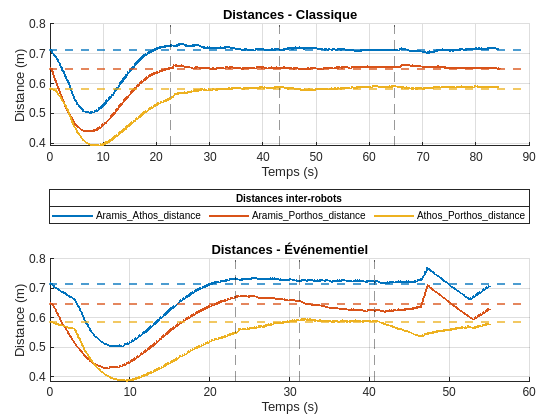

warning('off', 'all');

% === Tiled Layout ===
t = tiledlayout(2,1);
t.TileSpacing = 'compact';
t.Padding = 'compact';

% Subplot 1 : Classique
nexttile;
hold on; grid on;
y_values = data_classic{1, 2:end};  % on ignore la 1re colonne (temps)


legend_handles = gobjects(width(data_classic)-1, 1);  % pour stocker les handles
for i = 2:width(data_classic)
    legend_handles(i-1) = plot(time_classic, data_classic{:,i}, ...
        'DisplayName', strrep(data_classic.Properties.VariableNames{i}, '_', '\_'), ...
        'LineWidth', 1.5);
end
for i = 1:length(y_values)
    yline(y_values(i), '--', ...
        'Color', legend_handles(i).Color, ...
        'LineWidth', 1.5);
end
for i = 2:length(time_goal_classic)
    xline(time_goal_classic(i), 'k--', 'LineWidth', 1.2, 'Alpha', 0.4, 'HandleVisibility', 'off');
end
title('Distances - Classique');
xlabel('Temps (s)');
ylabel('Distance (m)');

% Subplot 2 : Événementiel
nexttile;
hold on; grid on;
y_values_ev = data_event{1, 2:end};  % on ignore la 1re colonne (temps)

for i = 1:length(y_values_ev)
    yline(y_values_ev(i), '--', ...
        'Color', legend_handles(i).Color, ...
        'LineWidth', 1.5);
end

for i = 2:width(data_event)
    plot(time_event, data_event{:,i}, ...
        'Color', legend_handles(i-1).Color, ...
        'LineWidth', 1.5);  % même couleur
end
for i = 2:length(time_goal_event)
    xline(time_goal_event(i), 'k--', 'LineWidth', 1.2, 'Alpha', 0.4, 'HandleVisibility', 'off');
end

title('Distances - Événementiel');
xlabel('Temps (s)');
ylabel('Distance (m)');

% === Légende globale manuelle ===
% On crée une figure invisible temporaire pour créer la légende
fig_leg = figure('Visible', 'off');
ax = axes(fig_leg);
copyobj(legend_handles, ax);  % on copie les courbes
legend(ax, 'Orientation', 'horizontal', 'Location', 'southoutside');
lgd = legend(ax, 'show');
close(fig_leg);  % on ferme la figure temporaire

% Ajout de la légende globale à la figure principale
lgd = legend(legend_handles, 'Orientation', 'horizontal', 'Location', 'southoutside');
lgd.Title.String = 'Distances inter-robots';

On note que les distances varient au lancement de l'algorithme, puis les robots convergent vers leurs positions voulues dans la formation (distance inter-robot relativement constante après que le premier point soit atteint)

### Commandes

robot_names = {};
timestamp_counts = [];
method_labels = {};  % Pour différencier classic/event dans le bargraph
timestamp_data = containers.Map;
dt_stats = containers.Map;
goal_points = [time_goal_classic,time_goal_event];

% --- CLASSIC ---
folder = 'classic';
files = dir(fullfile(base_path, folder, '*_cmd_vel_rate.csv'));
fprintf('\nClassic:\n');


Classic:


for i = 1:length(files)
    filename = fullfile(base_path, folder, files(i).name);
    data = readtable(filename, 'ReadVariableNames', false, 'Delimiter', ',');

    timestamps = datetime(data{:,1}, 'InputFormat', 'yyyy-MM-dd''T''HH:mm:ss.SSSSSS');
    timestamps_rel = seconds(timestamps - timestamps(1));

    robot_name = extractBefore(files(i).name, '_cmd_vel_rate.csv');
    full_name = [robot_name '_classic'];

    robot_names{end+1} = full_name;
    timestamp_data(full_name) = timestamps_rel;
    timestamp_counts(end+1) = numel(timestamps_rel);
    method_labels{end+1} = 'classic';

    delta_t = seconds(diff(timestamps));
    stats.mean = mean(delta_t);
    stats.std = std(delta_t);
    stats.min = min(delta_t);
    stats.max = max(delta_t);
    dt_stats(full_name) = stats;

    fprintf('\nRobot: %s\n', robot_name);
    fprintf('  N = %d commandes\n', numel(timestamps));
    fprintf('  Δt moyen    : %.4f s\n', stats.mean);
    fprintf('  Δt min      : %.4f s\n', stats.min);
    fprintf('  Δt max      : %.4f s\n', stats.max);
    fprintf('  Δt ec type  : %.4f s\n', stats.std);
end


Robot: Aramis


  N = 845 commandes


  Δt moyen    : 0.1000 s


  Δt min      : 0.0828 s


  Δt max      : 0.1156 s


  Δt ec type  : 0.0027 s



Robot: Athos


  N = 845 commandes


  Δt moyen    : 0.1000 s


  Δt min      : 0.0837 s


  Δt max      : 0.1158 s


  Δt ec type  : 0.0028 s



Robot: Porthos


  N = 845 commandes


  Δt moyen    : 0.1000 s


  Δt min      : 0.0851 s


  Δt max      : 0.1152 s


  Δt ec type  : 0.0027 s



% --- EVENT ---
folder = 'event';
files = dir(fullfile(base_path, folder, '*_cmd_vel_rate.csv'));
fprintf('\nEvent:\n');


Event:


for i = 1:length(files)
    filename = fullfile(base_path, folder, files(i).name);
    data = readtable(filename, 'ReadVariableNames', false, 'Delimiter', ',');

    timestamps = datetime(data{:,1}, 'InputFormat', 'yyyy-MM-dd''T''HH:mm:ss.SSSSSS');
    timestamps_rel = seconds(timestamps - timestamps(1));
    robot_name = extractBefore(files(i).name, '_cmd_vel_rate.csv');
    full_name = [robot_name '_event'];

    robot_names{end+1} = full_name;
    timestamp_data(full_name) = timestamps_rel;
    timestamp_counts(end+1) = numel(timestamps_rel);
    method_labels{end+1} = 'event';

    delta_t = seconds(diff(timestamps));
    stats.mean = mean(delta_t);
    stats.std = std(delta_t);
    stats.min = min(delta_t);
    stats.max = max(delta_t);
    dt_stats(full_name) = stats;

    fprintf('\nRobot: %s\n', robot_name);
    fprintf('  N = %d commandes\n', numel(timestamps));
    fprintf('  Δt moyen    : %.4f s\n', stats.mean);
    fprintf('  Δt min      : %.4f s\n', stats.min);
    fprintf('  Δt max      : %.4f s\n', stats.max);
    fprintf('  Δt ec type  : %.4f s\n', stats.std);
end


Robot: Aramis


  N = 181 commandes


  Δt moyen    : 0.2955 s


  Δt min      : 0.0961 s


  Δt max      : 9.4025 s


  Δt ec type  : 1.1582 s



Robot: Athos


  N = 202 commandes


  Δt moyen    : 0.2622 s


  Δt min      : 0.0983 s


  Δt max      : 9.3999 s


  Δt ec type  : 1.0201 s



Robot: Porthos


  N = 226 commandes


  Δt moyen    : 0.2364 s


  Δt min      : 0.0982 s


  Δt max      : 9.4007 s


  Δt ec type  : 0.9500 s


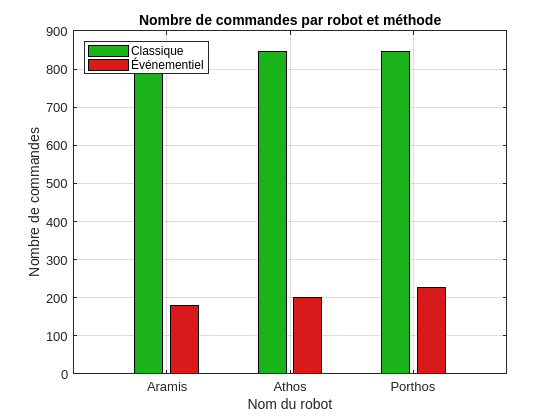


% Liste des robots (sans doublons)
robots = unique(extractBefore(robot_names, "_"));  % 'robot1', 'robot2', ...
methods = {'classic', 'event'};
n_robots = numel(robots);

% Données pour le bar chart
counts_matrix = zeros(n_robots, 2);  % une colonne pour classic, une pour event
for i = 1:n_robots
    for j = 1:2
        method = methods{j};
        full_name = robots{i} + "_" + method;
        if isKey(timestamp_data, full_name)
            counts_matrix(i, j) = numel(timestamp_data(full_name));
        else
            counts_matrix(i, j) = 0;
        end
    end
end

% Bar chart groupé
figure;
b = bar(categorical(robots), counts_matrix, 'grouped');
b(1).FaceColor = cl;  % Rouge classique
b(2).FaceColor = ev;   % Vert event

xlabel('Nom du robot');
ylabel('Nombre de commandes');
title('Nombre de commandes par robot et méthode');
legend({'Classique', 'Événementiel'}, 'Location', 'northwest');
grid on;

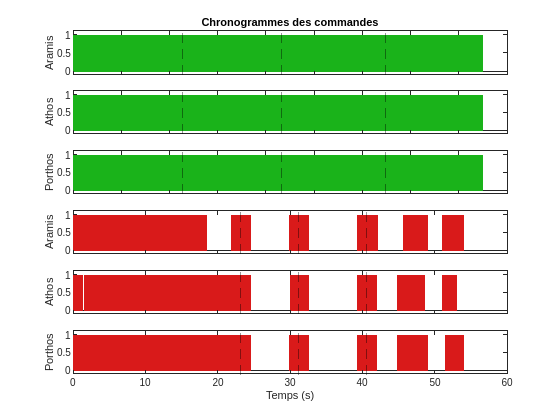



%% --- CHRONOGRAMMES BINAIRES ---
methods = {'classic', 'event'};
colors = {cl, ev};  % Rouge, Vert
robots = unique(extractBefore(robot_names, "_"));
n_robots = numel(robots);

figure;
for j = 1:2  % classic (1), puis event (2)
    points = goal_points(:,j);
    for i = 1:n_robots
        robot_name = robots{i};
        method = methods{j};
        color = colors{j};
        full_name = robot_name + "_" + method;

        if ~isKey(timestamp_data, full_name)
            warning("Pas de données pour %s", full_name);
            continue;
        end

        timestamps = timestamp_data(full_name);
        t_min = 0;
        t_max = ceil(max(timestamps));
        dt = 0.05;
        time_vector = t_min:dt:t_max;
        y = ismembertol(time_vector, timestamps, dt/2);

        idx = (j-1)*n_robots + i;
        subplot(n_robots*2, 1, idx);
        
        stem(time_vector, y, 'Marker', 'none', 'LineWidth', 1.2, 'Color', color);
        ylim([-0.1, 1.1]);
        ylabel([robot_name]);

        for i = 2:length(points)
            xline(points(i), 'k--', 'LineWidth', 1.2, 'Alpha', 0.4, 'HandleVisibility', 'off');
        end
        if idx == 1
            title('Chronogrammes des commandes');
        end
        if idx < n_robots*2
            set(gca, 'XTickLabel', []);
        else
            xlabel('Temps (s)');
        end
    end
end

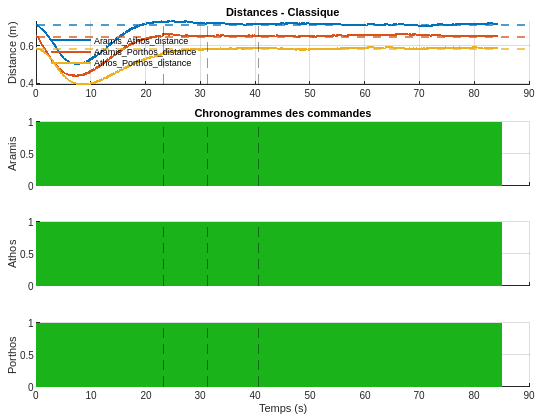

% === Tiled Layout ===
t = tiledlayout(4,1);  % 1 pour les distances + 3 pour les robots
t.TileSpacing = 'compact';
t.Padding = 'compact';

% Stocker les axes pour les synchroniser ensuite
axes_list = gobjects(n_robots + 1, 1);

%% === Subplot 1 : Distances ===
ax1 = nexttile;
axes_list(1) = ax1;
hold on; grid on;

legend_handles = gobjects(width(data_classic)-1, 1);
for i = 2:width(data_classic)
    legend_handles(i-1) = plot(time_classic, data_classic{:,i}, ...
        'DisplayName', strrep(data_classic.Properties.VariableNames{i}, '_', '\_'), ...
        'LineWidth', 1.5);
end
for i = 1:length(y_values)
    yline(y_values(i), '--', ...
        'Color', legend_handles(i).Color, ...
        'LineWidth', 1.5);
end

for i = 2:length(points)
    xline(points(i), 'k--', 'LineWidth', 1.2, 'Alpha', 0.4, 'HandleVisibility', 'off');
end

title('Distances - Classique');
ylabel('Distance (m)');
legend(legend_handles, 'Location', 'northwest', 'Box', 'off');

%% === Subplots 2 à 4 : Chronogrammes des robots ===
j = 1;
for i = 1:n_robots
    ax = nexttile;
    axes_list(i+1) = ax;
    hold on; grid on;

    robot_name = robots{i};
    method = methods{j};
    color = colors{j};
    full_name = robot_name + "_" + method;

    if ~isKey(timestamp_data, full_name)
        warning("Pas de données pour %s", full_name);
        continue;
    end

    timestamps = timestamp_data(full_name);
    t_min = 0;
    t_max = ceil(max(timestamps));
    dt = 0.05;
    time_vector = t_min:dt:t_max;
    y = ismembertol(time_vector, timestamps, dt/2);

    stem(time_vector, y, 'Marker', 'none', 'LineWidth', 1.2, 'Color', color);

    for k = 2:length(points)
        xline(points(k), 'k--', 'LineWidth', 1.2, 'Alpha', 0.4, 'HandleVisibility', 'off');
    end

    ylabel(robot_name);
    ylim([-0.1, 1.1]);

    if i == 1
        title('Chronogrammes des commandes');
    end

    if i < n_robots
        set(gca, 'XTickLabel', []);  % Supprimer les labels x sauf pour le dernier
    else
        xlabel('Temps (s)');
    end
end

%% === Synchroniser l'axe X entre tous les subplots ===
linkaxes(axes_list, 'x');

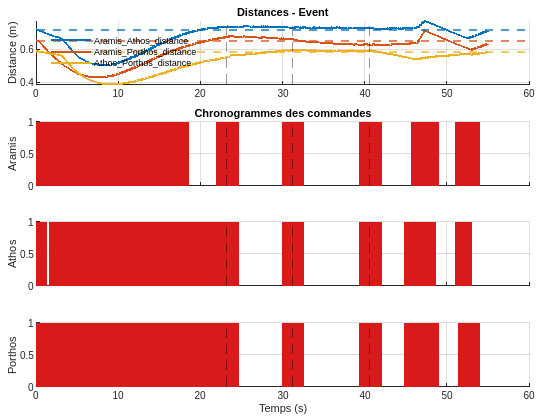

% === Tiled Layout ===
t = tiledlayout(n_robots + 1, 1);  % 1 pour les distances + 3 pour les robots
t.TileSpacing = 'compact';
t.Padding = 'compact';

% Stocker les axes pour les synchroniser ensuite
axes_list = gobjects(n_robots + 1, 1);

%% === Subplot 1 : Distances ===
ax1 = nexttile;
axes_list(1) = ax1;
hold on; grid on;

legend_handles = gobjects(width(data_classic)-1, 1);
for i = 2:width(data_classic)
    legend_handles(i-1) = plot(time_event, data_event{:,i}, ...
        'DisplayName', strrep(data_event.Properties.VariableNames{i}, '_', '\_'), ...
        'LineWidth', 1.5);
end
for i = 1:length(y_values_ev)
    yline(y_values_ev(i), '--', ...
        'Color', legend_handles(i).Color, ...
        'LineWidth', 1.5);
end

for i = 2:length(points)
    xline(points(i), 'k--', 'LineWidth', 1.2, 'Alpha', 0.4, 'HandleVisibility', 'off');
end

title('Distances - Event');
ylabel('Distance (m)');
legend(legend_handles, 'Location', 'northwest', 'Box', 'off');

%% === Subplots 2 à 4 : Chronogrammes des robots ===
j = 2;
for i = 1:n_robots
    ax = nexttile;
    axes_list(i+1) = ax;
    hold on; grid on;

    robot_name = robots{i};
    method = methods{j};
    color = colors{j};
    full_name = robot_name + "_" + method;

    if ~isKey(timestamp_data, full_name)
        warning("Pas de données pour %s", full_name);
        continue;
    end

    timestamps = timestamp_data(full_name);
    t_min = 0;
    t_max = ceil(max(timestamps));
    dt = 0.05;
    time_vector = t_min:dt:t_max;
    y = ismembertol(time_vector, timestamps, dt/2);

    stem(time_vector, y, 'Marker', 'none', 'LineWidth', 1.2, 'Color', color);

    for k = 2:length(points)
        xline(points(k), 'k--', 'LineWidth', 1.2, 'Alpha', 0.4, 'HandleVisibility', 'off');
    end

    ylabel(robot_name);
    ylim([-0.1, 1.1]);

    if i == 1
        title('Chronogrammes des commandes');
    end

    if i < n_robots
        set(gca, 'XTickLabel', []);  % Supprimer les labels x sauf pour le dernier
    else
        xlabel('Temps (s)');
    end
end


%% === Synchroniser l'axe X entre tous les subplots ===
linkaxes(axes_list, 'x');